# Here we devlop depressive disorders vs controls signatures using rs-fMRI connectivity data

## study 6

clear, clc
datadir = 'G:\A_arousal_analysis\data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'))
load(fullfile(datadir, 'FC_UESTC_s6.mat'))

FC = atanh(FC);
FC(isnan(FC)) = 0;
FC(~isfinite(FC)) = 0;
FC = FC(32:end, parcel_idx);
label = [ones(34, 1); -ones(33, 1)];
nsample = numel(label);

CV = (1:nsample)';
pred_label = zeros(nsample,1);
for i = 1:nsample
    train_idx = CV ~= i;
    test_idx = CV == i;
    svmobj = svm({'C=1', 'optimizer="andre"', kernel('linear')});
    dataobj = data('spider data', FC(train_idx,:), label(train_idx));
    [~, svmobj] = train(svmobj, dataobj, loss);
    weight = get_w(svmobj);
    bias = svmobj.b0;
    pred_label(test_idx,:) = FC(test_idx,:) * weight'+bias;
end

training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm

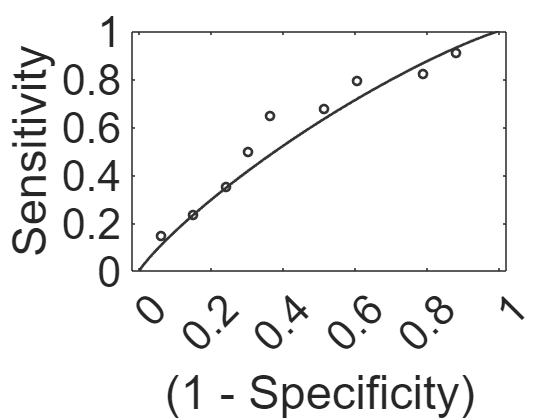

% roc_plot uses "0" and "1"
figure;
roc = roc_plot(pred_label, label > 0, 'threshold', 0, 'nooutput'); 

fprintf('\n Study 6 cross-validated prediction: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 6 cross-validated prediction: ACC = 62.69% ± 5.909%, P = 0.066, AUC = 0.64, d = 0.31 



svmobj = svm({'C=1', 'optimizer="andre"', kernel('linear')});
dataobj = data('spider data', FC, label);
[~, svmobj] = train(svmobj, dataobj, loss);

training svm kernel linear C=1 optimizer=andre.... 


weight = get_w(svmobj);
bias = svmobj.b0;
save(fullfile(datadir, "A_MDD_decoder_study6.mat"), 'weight', 'bias');

## study 7

clear, clc
datadir = 'G:\A_arousal_analysis\data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'))
load(fullfile(datadir, 'FC_Chongqing_s6.mat'))

FC = atanh(FC);
FC(isnan(FC)) = 0;
FC(~isfinite(FC)) = 0;
label = [-ones(24, 1); ones(30, 1)];
included =  patient ~=2;
FC = FC(included, parcel_idx);
label = label(included);
nsample = numel(label);

CV = (1:nsample)';
pred_label = zeros(nsample,1);
for i = 1:nsample
    train_idx = CV ~= i;
    test_idx = CV == i;
    svmobj = svm({'C=1', 'optimizer="andre"', kernel('linear')});
    dataobj = data('spider data', FC(train_idx,:), label(train_idx));
    [~, svmobj] = train(svmobj, dataobj, loss);
    weight = get_w(svmobj);
    bias = svmobj.b0;
    pred_label(test_idx,:) = FC(test_idx,:) * weight'+bias;
end

training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm

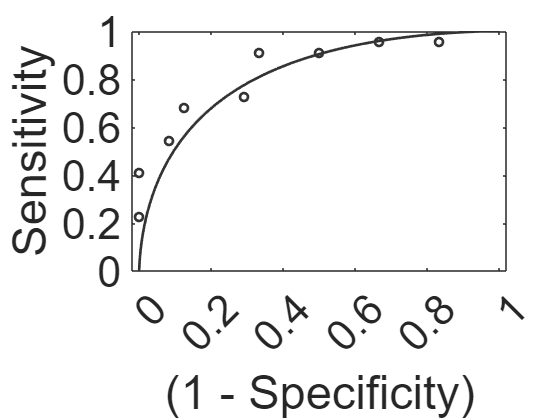

figure;
roc = roc_plot(pred_label, label > 0, 'threshold', 0, 'nooutput');

fprintf('\n Study 7 cross-validated prediction: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 7 cross-validated prediction: ACC = 73.91% ± 6.474%, P = 0.0043, AUC = 0.85, d = 1.3 



svmobj = svm({'C=1', 'optimizer="andre"', kernel('linear')});
dataobj = data('spider data', FC, label);
[~, svmobj] = train(svmobj, dataobj, loss);

training svm kernel linear C=1 optimizer=andre.... 


weight = get_w(svmobj);
bias = svmobj.b0;
save(fullfile(datadir, "A_MDD_decoder_study7.mat"), 'weight', 'bias');

## study 8

clear, clc
datadir = 'G:\A_arousal_analysis\data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'))
load(fullfile(datadir, 'FC_Chongqing2_s6.mat'))

FC = atanh(FC);
FC(~isfinite(FC)) = 0;
FC = FC(~excluded, parcel_idx);
label = label(~excluded);
label(label==0) = -1;
nsample = numel(label);

CV = (1:nsample)';
pred_label = zeros(nsample,1);
for i = 1:nsample
    train_idx = CV ~= i;
    test_idx = CV == i;
    svmobj = svm({'C=1', 'optimizer="andre"', kernel('linear')});
    dataobj = data('spider data', FC(train_idx,:), label(train_idx));
    [~, svmobj] = train(svmobj, dataobj, loss);
    weight = get_w(svmobj);
    bias = svmobj.b0;
    pred_label(test_idx,:) = FC(test_idx,:) * weight'+bias;
end

training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm

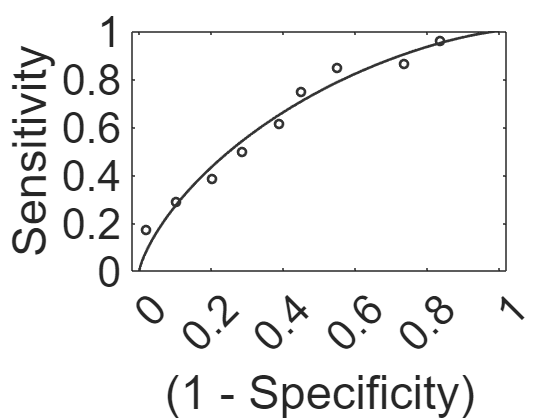

figure;
roc = roc_plot(pred_label, label > 0, 'threshold', 0, 'nooutput');

fprintf('\n Study 8 cross-validated prediction: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 8 cross-validated prediction: ACC = 61.39% ± 4.844%, P = 0.058, AUC = 0.69, d = 0.67 



svmobj = svm({'C=1', 'optimizer="andre"', kernel('linear')});
dataobj = data('spider data', FC, label);
[~, svmobj] = train(svmobj, dataobj, loss);

training svm kernel linear C=1 optimizer=andre.... 


weight = get_w(svmobj);
bias = svmobj.b0;
save(fullfile(datadir, "A_MDD_decoder_study8.mat"), 'weight', 'bias');

## study 9

clear, clc
datadir = 'G:\A_arousal_analysis\data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'))
load(fullfile(datadir, 'FC_BANDA_s6.mat'))

FC_run1 = atanh(FC_run1);
FC_run1(FC_run1==0) = NaN;
FC_run1(~isfinite(FC_run1)) = NaN;
FC_run1(outlier_run1,:) = NaN; % num of spikes > num of timepoints * 0.25
FC_run2 = atanh(FC_run2);
FC_run2(FC_run2==0) = NaN;
FC_run2(~isfinite(FC_run2)) = NaN;
FC_run2(outlier_run2,:) = NaN; % num of spikes > num of timepoints * 0.25

FC = [];
FC(:, :, 1) = FC_run1;
FC(:, :, 2) = FC_run2;
clear FC_*
FC = mean(FC, 3, 'omitnan');
FC = FC(:, parcel_idx);
excluded_fmri = outlier_run1 & outlier_run2;

T = readtable(fullfile(datadir, 'ndar_subject01.csv'),'VariableNamingRule', 'preserve', 'TreatAsEmpty', 'n/a');
control = false(206,1);
depression = false(206,1);
anxiety = false(206,1);
for i = 1:206
    idx = strcmp(T.src_subject_id, subIDs{i}(5:end)) & strcmp(T.visit,'T1');
    if sum(idx) == 1
    if strcmp(T.phenotype(idx),'Control')
        control(i) = true;
    elseif strcmp(T.phenotype(idx),'Depression')
        depression(i) = true;
    elseif strcmp(T.phenotype(idx),'Anxiety')
        anxiety(i) = true;
    end
    end
end

FC_depr = FC(depression & ~excluded_fmri,:);
FC_con = FC(control & ~excluded_fmri,:);
clear FC
ndepr = size(FC_depr, 1);
ncon = size(FC_con, 1);
label = [ones(ndepr,1); -ones(ncon, 1)];
FC = [FC_depr; FC_con];
nsample = numel(label);

CV = (1:nsample)';
pred_label = zeros(nsample,1);
for i = 1:nsample
    train_idx = CV ~= i;
    test_idx = CV == i;
    svmobj = svm({'C=1', 'optimizer="andre"', kernel('linear')});
    dataobj = data('spider data', FC(train_idx,:), label(train_idx));
    [~, svmobj] = train(svmobj, dataobj, loss);
    weight = get_w(svmobj);
    bias = svmobj.b0;
    pred_label(test_idx,:) = FC(test_idx,:) * weight'+bias;
end

training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm kernel linear C=1 optimizer=andre.... 
training svm

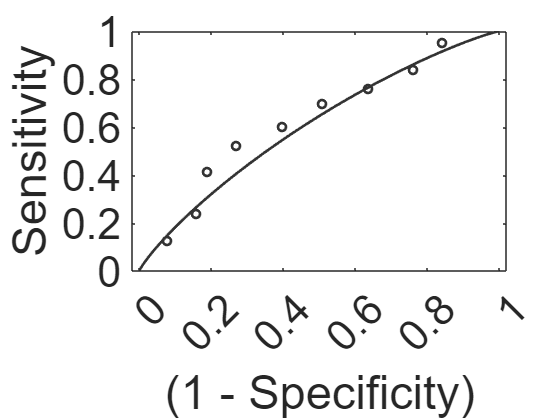


figure;
roc = roc_plot(pred_label, label > 0, 'threshold', 0, 'nooutput');

fprintf('\n Study 9 cross-validated prediction: ACC = %.04g%% ± %.04g%%, P = %.02g, AUC = %.02g, d = %.02g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 9 cross-validated prediction: ACC = 59.52% ± 4.373%, P = 0.04, AUC = 0.64, d = 0.38 



svmobj = svm({'C=1', 'optimizer="andre"', kernel('linear')});
dataobj = data('spider data', FC, label);
[~, svmobj] = train(svmobj, dataobj, loss);

training svm kernel linear C=1 optimizer=andre.... 


weight = get_w(svmobj);
bias = svmobj.b0;
save(fullfile(datadir, "A_MDD_decoder_study9.mat"), 'weight', 'bias');